# Deep Learning Data Synthesis for 5G Channel Estimation

In this example we will showcase how to train a Convolutional Neural network (CNN) for channel estimation. Using the trained CNN, we will perform channel estimation in single-input single-output (SISO) mode, utilizing the physical downlink shared channel (PDSCH) demodulation reference signal (DM-RS).

*Copyright 2022 The MathWorks, Inc.*

## Introduction

The general approach to channel estimation is to insert known reference pilot symbols into the transmission and then interpolate the rest of the channel response by using these pilot symbols.

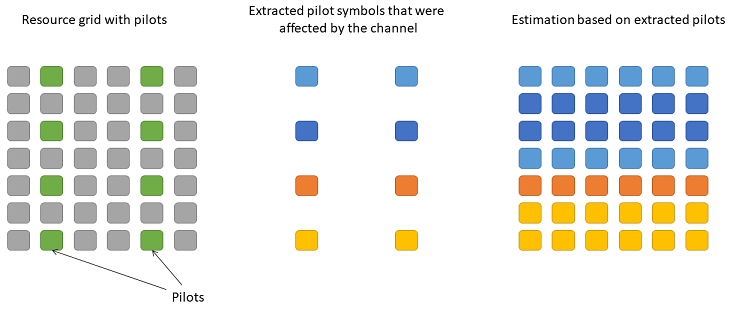

We can also use deep learning techniques to perform channel estimation. For example, by viewing the resource grid as a 2-D image, we can turn the problem of channel estimation into an image processing problem where CNNs are effective.

In this exercise we will:

- Generate standard-compliant waveforms and channel models to use as training data 

- Train a CNN for channel estimation

- Use network to process images that contain linearly interpolated received pilot symbols 

- Compare the results of the neural network channel estimator to practical and perfect estimators

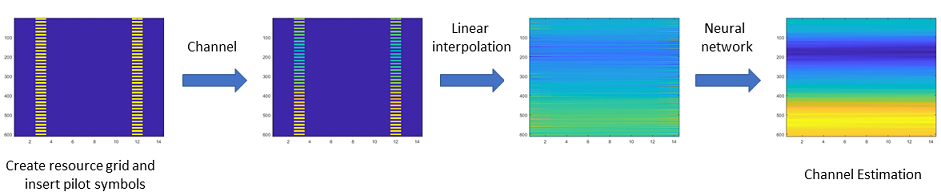

## Are You in the Correct Directory?

% Run this to check proper configuration 

% Start from a clean workspace
clearvars

if isfolder('3-HelperFiles')
 disp('You are in the correct directory. Please continue.')
 addpath('3-HelperFiles') 
 
else 
 error('Please navigate to the proper Directory')
end

You are in the correct directory. Please continue.


## **Generate Synthetic Data **

We will now generate data to produce 256 data samples. This amount of data is sufficient to train a functional channel estimation network in a reasonable time.

The function [hGenerateTrainingData](matlab:open('./3-HelperFiles\hGenerateTrainingData.m')) does the following:

- Create random channel configurations 

- Pass ans OFDM-modulated fixed resource grid with only the DM-RS symbols inserted

- Perform perfect timing synchronization and OFDM demodulation

- Extract the pilot symbols and perform linear interpolation 

- Use perfect channel information to create the label data

- Split data into training (200 samples) and validation data (56 samples)

% Generate the training data
[trainData,trainLabels,valData, valLabels] = hGenerateTrainingData(256);

Starting data generation...
12.50% complete
25.00% complete
37.50% complete
50.00% complete
62.50% complete
75.00% complete
87.50% complete
100.00% complete
Data generation complete!


## Preprocess Data for CNN

In a channel estimation scenario, the resource grids have complex data. Therefore, we need input the real and imaginary parts of these grids separately to the CNN.

Since the CNN treats the resource grids as 2-D images, for our the training data with 612 subcarriers and 14 OFDM sysmbols we converted   a complex 612 -by-14 matrix into a real-valued 612-by-14-by-2 matrix, where the third dimension denotes the real and imaginary components. 

To ensure that the CNN does not overfit the training data, we also split the dataset such that 200 samples are used for training and 56 samples are used for validation

% Observe the dimensions of training and validation data
whos 

  Name               Size                     Bytes  Class     Attributes

  trainData        612x14x2x200            27417600  double              
  trainLabels      612x14x2x200            27417600  double              
  valData          612x14x2x56              7676928  double              
  valLabels        612x14x2x56              7676928  double              



## Create Network Architecture 

**TO DO: Add an imageInputLayer to the network with appropriate input size**

- Dim 1:  Number of subcarriers 

- Dim 2:  Number of OFDM sysmbols

- Dim 3:  2 (I and Q samples)

% Define the CNN structure
layers = [ 
 imageInputLayer([612, 14, 2])  
 convolution2dLayer(5,32,'Padding',2)
 reluLayer
 convolution2dLayer(5,32,'Padding',2)
 reluLayer
 convolution2dLayer(5,32,'Padding',2)
 reluLayer
 convolution2dLayer(5,2,'Padding',2)
 regressionLayer
 ];


## Set Training Options for Training 

 The validation data is used for monitoring the performance of the trained neural network at regular intervals. We stop training when the validation loss stops improving. 

**TO DO: Find the network with the lowest training/validation RMSE **

Try different combinations of  maxEpochs and InitialLearnRate to improve network accuracy  

- maxEpochs: 10, 50, and 100

- InitialLearnRate: 0.001 and 0.0001 

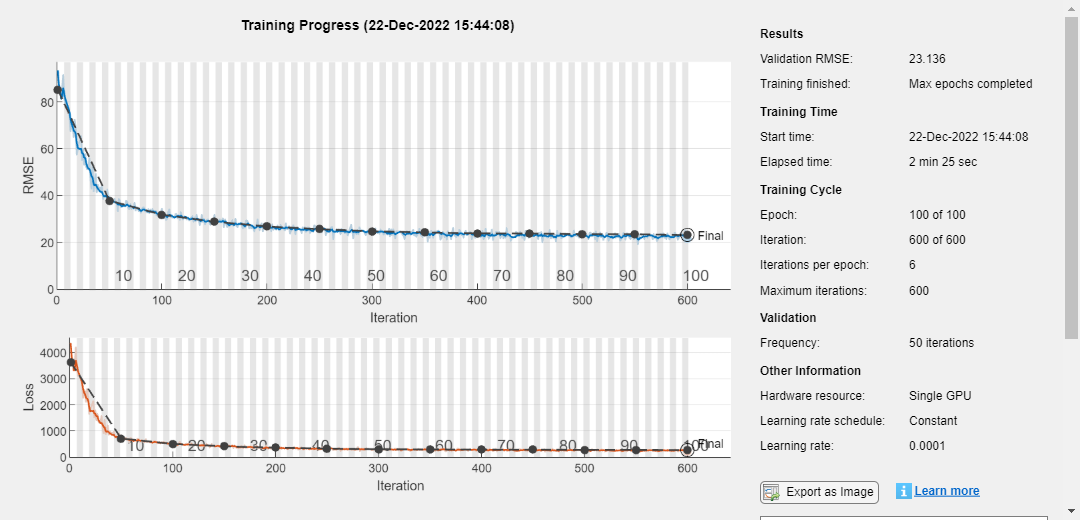

% Set the maximum number of epochs 
maxEpochs = 100;

% Set the initial learning rate
initialLearnRate = 0.0001;

% Set training options 
options = trainingOptions('adam', ...
 'InitialLearnRate',initialLearnRate, ...
 'MaxEpochs',maxEpochs, ...
 'MiniBatchSize',32, ...
 'Shuffle','every-epoch', ...
 'Verbose',false, ...
 'Plots','training-progress', ...
 'ValidationData',{valData, valLabels});

% Train the network
[net,info] = trainNetwork(trainData, trainLabels,layers,options);

rmseTrain = info.TrainingRMSE(end)

rmseTrain = 21.4754

rmseVal= info.ValidationRMSE(end)

rmseVal = 23.1363

## Generate Test Resource Grid 

To generate a test resource grid, we create a TDL channel Model and simulate a PDSCH DM-RS transmission. Note: Only SISO configuration is supported. 

In addition, we also perform 5G practical channel estimation and use it as a golden reference for comparing it with our Neural Network based channel estimation.  

The function [hChannelModel](matlab:open('./3-HelperFiles\hChannelModel.m')) does the following:

- Generate the resource grid

- Insert DM-RS symbols

- Perform OFDM modulation

- Send modulated waveform through the channel model

- Add white Gaussian noise

- Perform perfect timing synchronization

- Perform OFDM demodulation

- Perform practical channel estimation using [nrChannelEstimate](https://www.mathworks.com/help/5g/ref/nrchannelestimate.html)

[interpChannelGrid, estChannelGrid, actualChannel] = hChannelModel();

## Perform Channel Estimation using CNN 

To perform channel estimation using the neural network, we split the interpolated image into its real and imaginary parts, input these together into the neural network as a single batch and finally, concatenate and transform the results back into complex data.

We conclude by visualizing the results of the neural network channel estimator in comparison to the practical  estimator.

**To Do:** **Use the **[**predict**](https://www.mathworks.com/help/releases/R2022a/deeplearning/ref/seriesnetwork.predict.html)** command to perform channel estimation on the interpolated test grid**

- `Argument_1 = Variable name for network`

- `Argument_2 = Variable name for test rsource grid`

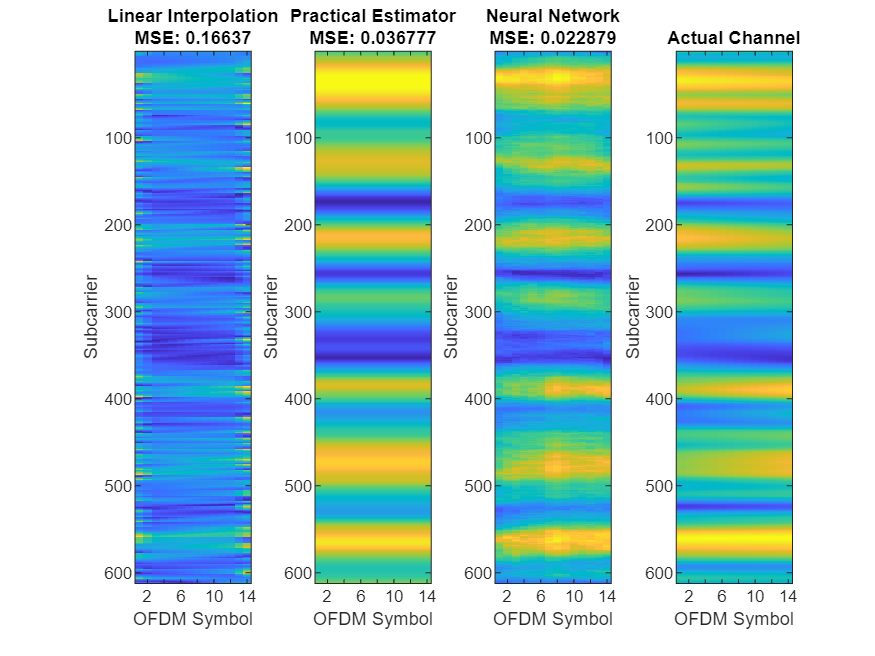

% Concatenate the real and imaginary grids along the channel dimension
testGrid = cat(3,real(interpChannelGrid),imag(interpChannelGrid));

% Use the neural network to estimate the channel
estChannelGridNN = predict(net,testGrid);

% Convert results to complex 
estChannelGridNN = complex(estChannelGridNN(:,:,1),estChannelGridNN(:,:,2));

% Compare Various Channel Estimations using Mean Squared Error
hPlotChEstimates(interpChannelGrid,estChannelGrid,estChannelGridNN,actualChannel);

Both the practical estimator and the neural network estimator outperform linear interpolation. Depending on the network created, in some cases, neural network estimator performs better than the practical estimator. 

## Further Exploration

It is possible to optimize the hyperparameters parameters, such as number of filters, filter size, or optimize the network structure, such as adding more layers, using different activation layers, etc. to improve the accuracy.

For more information refer to the following documentation example:

[https://www.mathworks.com/help/5g/ug/deep-learning-data-synthesis-for-5g-channel-estimation.html](https://www.mathworks.com/help/5g/ug/deep-learning-data-synthesis-for-5g-channel-estimation.html)

## References

- van de Beek, Jan–Jaap, Ove Edfors, Magnus Sandell, Sarah Kate Wilson, and Per Ola Borjesson. “On Channel Estimation in OFDM Systems.” In 1995 IEEE 45th Vehicular Technology Conference. Countdown to the Wireless Twenty–First Century, 2:815–19, July 1995.

- Ye, Hao, Geoffrey Ye Li, and Biing-Hwang Juang. “Power of Deep Learning for Channel Estimation and Signal Detection in OFDM Systems.” IEEE Wireless Communications Letters 7, no. 1 (February 2018): 114–17.

- Soltani, Mehran, Vahid Pourahmadi, Ali Mirzaei, and Hamid Sheikhzadeh. “Deep Learning–Based Channel Estimation.” Preprint, submitted October 13, 2018.

## Additional Resources

- [Overview: AI for Wireless Communications](https://www.mathworks.com/solutions/wireless-communications/ai.html)

- [Examples: Deep Learning in Wireless Systems](https://www.mathworks.com/help/comm/deep-learning-in-wireless-systems.html)